# Real-Time Emotion Recognition from USB Camera with Deep CNNs

## 1. Entire Workflow 

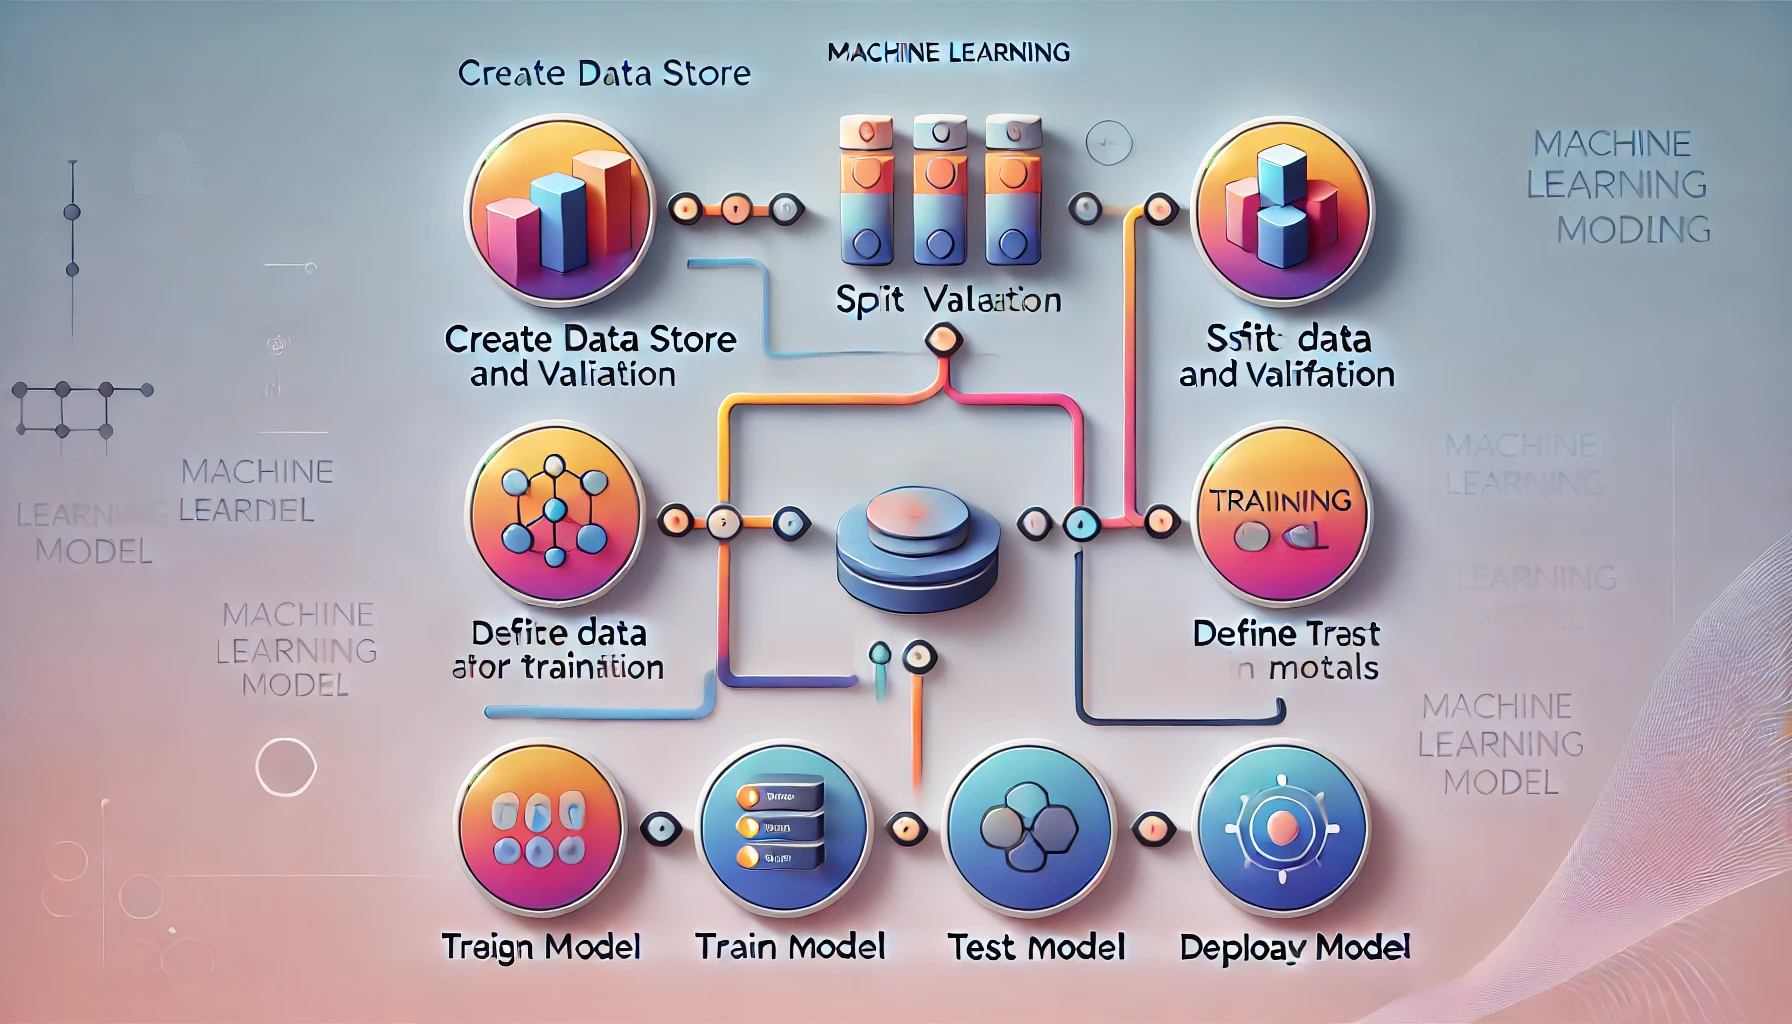

**How CNNs Work:  **A convolutional neural network can have hundreds of layers and each layer learn to detect different features of an image. Filters are applied to each training image at different resolutions and size, and the output of each involved image is used as the input to the next layer. The filters can start as very simple features, such as brightness and edges, and later on it goes deep to extract complex features. Like other neural networks, a CNN is composed of an input layer, an output layer, and many hidden layers in between.

## **2. Download Dataset from Kaggle**

Open the Firefox browser. Then, download the CK+ dataset page on Kaggle

% firefox 'https://www.kaggle.com/datasets/shawon10/ckplus'


## 3. Create Image Datastore

% Define the folder path where images are stored
folderPath = 'CK+48';

% Create an imageDatastore to load images from the specified folder
imds = imageDatastore(folderPath, ...
    'IncludeSubfolders', true, ...      % Include images from subfolders
    'LabelSource', 'foldernames');     % Use folder names as labels

% Optionally, check the contents of the imageDatastore
% Display information about the dataset
disp(imds);

  ImageDatastore with properties:

                       Files: {
                              ' .../detecting-emotion-cnn-20241128-1900/CK+48/anger/S010_004_00000017.png';
                              ' .../detecting-emotion-cnn-20241128-1900/CK+48/anger/S010_004_00000018.png';
                              ' .../detecting-emotion-cnn-20241128-1900/CK+48/anger/S010_004_00000019.png'
                               ... and 978 more
                              }
                     Folders: {
                              '/MATLAB Drive/FileExchange/detecting-emotion-cnn-20241128-1900/CK+48'
                              }
                      Labels: [anger; anger; anger ... and 978 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
             

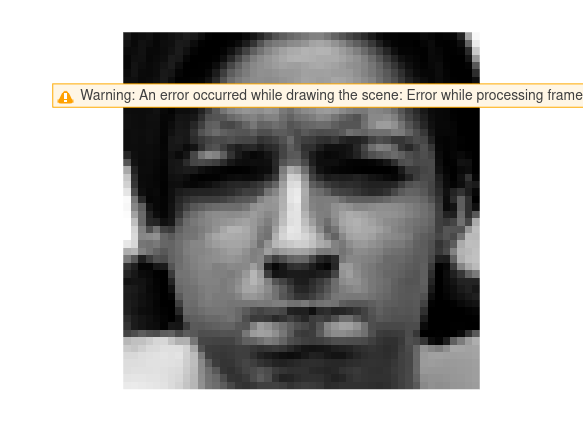

% disp(['Number of training samples: ', num2str(numel(imdstrain.Files))]);
%disp(['Number of validation samples: ', num2str(numel(imdsvalid.Files))]);

% Example of reading an image from the datastore
sampleImage = read(imds);

% Display the image
imshow(sampleImage);
title('Sample Image from CK+ dataset');

## 4. Split Data for Training and validation

% Split the imageDatastore into training and validation sets
% 80% of the data will be used for training and 20% for validation.
[imdstrain, imdsvalid]=splitEachLabel(imds, 0.8,'randomize');

% Count the number of images in each class (label) in the entire datastore
CountLabel = imds.countEachLabel

CountLabel = 7x2 table
     Label      Count
    ________    _____

    anger        135 
    contempt      54 
    disgust      177 
    fear          75 
    happy        207 
    sadness       84 
    surprise     249 



% Read a single image from the datastore to check its format and size
sampleImage = read(imds);

% Get the dimensions of the sample image (height, width, and channels)
size(sampleImage)

ans =     48    48


## 5. Define the Network Layers

Define the convolutional neural network architecture. 

To improve image recognition performance, there are various ways to add deeper layers to the model. Adding more layers allows the model to learn more complex features, but if the model becomes too deep, it may lead to overfitting or increased computational cost. Therefore, it is important to efficiently increase the depth of the model when expanding it.

Below is an extended CNN architecture that includes additional layers. The model has been made deeper and more powerful by adding more **convolutional layers**, **max pooling layers**, and **fully connected layers**.


layers = [
    % Image Input Layer: Accepts grayscale images of size 48x48
    imageInputLayer([48 48 1]) 
    
    % 1. First Convolutional Layer: Applies 8 filters of size 3x3 with same padding
    convolution2dLayer(3, 8, 'Padding', 'same')
    
    % Batch Normalization: Normalizes activations to improve training stability
    batchNormalizationLayer
    
    % ReLU Activation: Introduces non-linearity and helps with the training process
    reluLayer
    
    % Max Pooling Layer: Reduces spatial dimensions by applying a 2x2 pool with stride 2
    maxPooling2dLayer(2, 'Stride', 2)
    
    % 2. Second Convolutional Layer: Applies 16 filters of size 3x3 with same padding
    convolution2dLayer(3, 16, 'Padding', 'same')
    
    % Batch Normalization: Again normalizes activations for stability
    batchNormalizationLayer
    
    % ReLU Activation: Non-linear activation to improve learning capabilities
    reluLayer
    
    % Max Pooling Layer: Reduces the size of the feature map by half (2x2 pool)
    maxPooling2dLayer(2, 'Stride', 2)
    
    % 3. Third Convolutional Layer: Applies 32 filters of size 3x3 with same padding
    convolution2dLayer(3, 32, 'Padding', 'same')
    
    % Batch Normalization: Stabilizes the learning by normalizing activations
    batchNormalizationLayer
    
    % ReLU Activation: Adds non-linearity for improved learning
    reluLayer
    
    % Max Pooling Layer: Reduces the size of the feature map by half (2x2 pool)
    maxPooling2dLayer(2, 'Stride', 2)
    
    % 4. Fourth Convolutional Layer: Applies 64 filters of size 3x3 with same padding
    convolution2dLayer(3, 64, 'Padding', 'same')
    
    % Batch Normalization: Normalizes activations to improve training stability
    batchNormalizationLayer
    
    % ReLU Activation: Non-linear activation to improve learning capabilities
    reluLayer
    
    % Fifth Convolutional Layer: Applies 128 filters of size 3x3 with same padding
    convolution2dLayer(3, 128, 'Padding', 'same')
    
    % Batch Normalization: Again normalizes activations for stability
    batchNormalizationLayer
    
    % ReLU Activation: Adds non-linearity for improved learning
    reluLayer
    
    % Max Pooling Layer: Reduces the size of the feature map by half (2x2 pool)
    maxPooling2dLayer(2, 'Stride', 2)
    
    % Fully Connected Layer: Output layer with 512 units
    fullyConnectedLayer(512)
    
    % ReLU Activation: Non-linear activation for the fully connected layer
    reluLayer
    
    % Fully Connected Layer: Output layer with 7 units (for 7 classes)
    fullyConnectedLayer(7)
    
    % Softmax Layer: Converts logits to probabilities for classification
    softmaxLayer
    
    % Classification Layer: Computes the cross-entropy loss for classification
    classificationLayer];


## 6. Define Option for Training

% Define training options for the network
options = trainingOptions('sgdm', ...
    'InitialLearnRate', 0.02, ...         % Set the initial learning rate for the optimizer
    'MaxEpochs', 20, ...                  % Set the maximum number of epochs to train
    'Shuffle', 'every-epoch', ...         % Shuffle the data at the beginning of each epoch
    'ValidationFrequency', 10, ...        % Validate the model every 10 iterations
    'Verbose', false, ...                 % Disable the display of detailed output during training
    'Plots', 'training-progress');        % Enable the progress plot to monitor training


## 7. Train Model

% Train the convolutional neural network using the training data and specified network architecture
convnet = trainNetwork( ...
    imdstrain, ...              % The image datastore containing the training data
    layers, ...                 % The layers of the convolutional neural network
    options ...                 % The training options (e.g., learning rate, epochs, etc.)
);


## 8. Calculate Accuracy using Validation Dataset

**8.1 Classification**

% Classify the images in the validation dataset using the trained network
YPred = classify(convnet, imdsvalid);  % Predict labels for the validation dataset

% Extract the true labels from the validation dataset
YValidation = imdsvalid.Labels;       % True labels of the validation data

% Calculate the classification accuracy by comparing predicted and true labels
accuracy = sum(YPred == YValidation) / numel(YValidation);  % Accuracy = correct predictions / total predictions


**8.2 Confusion Matrix**

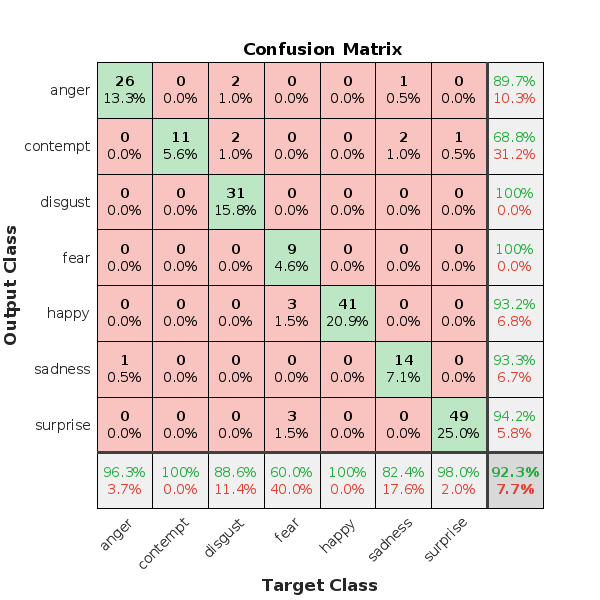

% Plot the confusion matrix to visualize the classification performance
% The confusion matrix compares the true labels (YValidation) with the predicted labels (YPred)
plotconfusion(YValidation, YPred);  % Displays the confusion matrix for the validation data

**8.3 Read an image from datastore and predict the class **

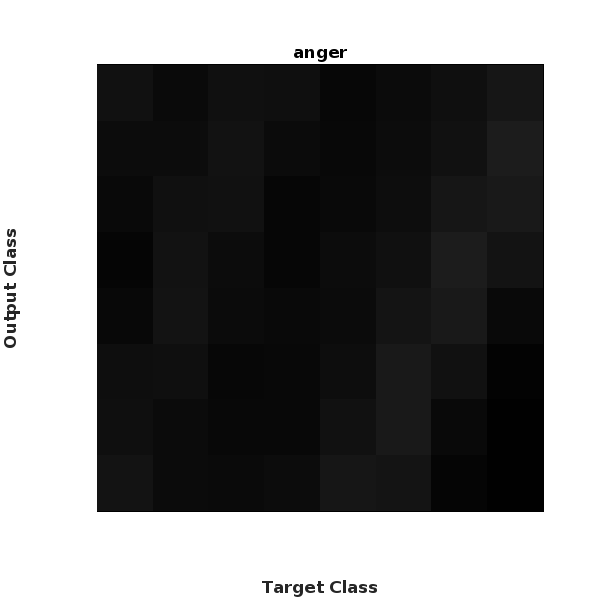

% Read a single image from the validation datastore (imdsvalid)
a = read(imdsvalid);  % 'a' is the image data read from the datastore

% Classify the image using the trained convolutional neural network (convnet)
class = classify(convnet, a);  % 'class' is the predicted label for the image

% Display the image
imshow(a);  % Show the image in a figure window

% Add the predicted class label as the title of the image
title(string(class));  % Display the predicted class label on top of the image

## 9. Interface with live Camera

% camera = webcam(1);
%  - Connect to the camera

% camera = ipcam('http://192.168.225.88:8080/video');
%  - paste the same url as show in the IP Webcam app.


% Clear any existing camera objects to ensure fresh connection
clear camera;  

% Create a new figure window for displaying the webcam feed
figure;

% Initialize the webcam (camera 1 in this case)
camera = webcam(20);  % Select the first available webcam

Webcam access is not supported in this browser. Use Google Chrome instead.


% Infinite loop to continuously capture and process images from the webcam
while true   
    % Capture a snapshot (image) from the webcam
    im = camera.snapshot;  
    
    % Convert the captured image to grayscale (for easier processing)
    picture = rgb2gray(im);  
    
    % Resize the grayscale image to 48x48 pixels, as required by the CNN input
    picture = imresize(picture, [48, 48]);  
    
    % Classify the resized image using the trained neural network (convnet)
    label = classify(convnet, picture);  
    
    % Optionally, send the classification result to an IoT platform (e.g., ThingSpeak)
    % thingSpeakWrite(467220, 0, 'WriteKey', 'H5TEVABDP00IFYKM');  

    % Display the live image from the webcam
    image(im);  
    
    % Display the predicted label as the title of the image
    title(char(label));  
    
    % Update the figure window with the new image and label
    drawnow;   
end
